# tmem16 widefield spatial analysis

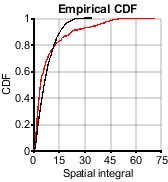

tmem1 = load('spatialAnalysis196_3.mat');
tmem2 = load('spatialAnalysis208_2.mat');
tmem3 = load('spatialAnalysis326_3.mat');
tmem4 = load('spatialAnalysis242_2.mat');
tmem5 = load('spatialAnalysis203_3.mat');
tmem6 = load('spatialAnalysis235_3.mat');
% others have too much rotational movement around edges even with moco

tectaTM1 = load('spatialAnalysis203_1.mat');
tectaTM2 = load('spatialAnalysis208_1.mat');
tectaTM3 = load('spatialAnalysis326_2.mat');
tectaTM4 = load('spatialAnalysis214_1.mat');
tectaTM5 = load('spatialAnalysis235_2.mat');
tectaTM6 = load('spatialAnalysis203_2.mat'); % dim retinal waves
tectaTM7 = load('spatialAnalysis242_1.mat');
tectaTM8 = load('spatialAnalysis280_1.mat');

%tmemInt1 = [mean(tmem1.eventStats.integral),mean(tmem2.eventStats.integral)];
%tmemIntNorm1 = [mean(tmem1.eventStats.integralnorm),mean(tmem2.eventStats.integralnorm)];

tmemInt = [tmem1.eventStats.integral,tmem2.eventStats.integral,tmem3.eventStats.integral,tmem4.eventStats.integral,tmem5.eventStats.integral,tmem6.eventStats.integral];
tectaTMInt = [tectaTM1.eventStats.integral,tectaTM2.eventStats.integral,tectaTM3.eventStats.integral,tectaTM4.eventStats.integral,tectaTM5.eventStats.integral,tectaTM6.eventStats.integral,tectaTM7.eventStats.integral,tectaTM8.eventStats.integral];


conditions2 = {'Control','cKO'};
dim = [1 2];
% 
% % frequency
% ylbl1 = 'Mean spatial integral';
% [fig1 h p1] = compare2(tmemFreq,tectaTMFreq,conditions2,ylbl1,dim);
% ylim([0 20])
% p1


figure
h1 = cdfplot(tectaTMInt);
hold on
h2 = cdfplot(tmemInt);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Spatial integral');
ylabel('CDF');
xlim([0 75])
xticks([0 15 30 45 60 75])
figQuality(gcf,gca,[1.75 1.9])

[h p] = kstest2(tmemInt,tectaTMInt);
 p

p = 6.0867e-11

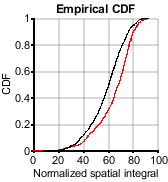

 

tmemIntNorm = [tmem1.eventStats.integralnorm,tmem2.eventStats.integralnorm,tmem3.eventStats.integralnorm,tmem4.eventStats.integralnorm,tmem5.eventStats.integralnorm,tmem6.eventStats.integralnorm];
tectaTMIntNorm = [tectaTM1.eventStats.integralnorm,tectaTM2.eventStats.integralnorm,tectaTM3.eventStats.integralnorm,tectaTM4.eventStats.integralnorm,tectaTM5.eventStats.integralnorm,tectaTM6.eventStats.integralnorm,tectaTM7.eventStats.integralnorm,tectaTM8.eventStats.integralnorm];

figure
h1 = cdfplot(tectaTMIntNorm);
hold on
h2 = cdfplot(tmemIntNorm);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized spatial integral');
ylabel('CDF');
xlim([0 100])
xticks([0 20 40 60 80 100])
figQuality(gcf,gca,[1.75 1.9])

[h p] = kstest2(tmemIntNorm,tectaTMIntNorm);
 p

p = 3.1332e-17


  % locations of events
tmemLoc = [tmem1.eventStats.xloc,tmem2.eventStats.xloc,tmem3.eventStats.xloc,tmem4.eventStats.xloc,tmem5.eventStats.xloc,tmem6.eventStats.xloc]*scale-50;

Unrecognized function or variable 'scale'.

tectaTMLoc = [tectaTM1.eventStats.xloc,tectaTM2.eventStats.xloc,tectaTM3.eventStats.xloc,tectaTM4.eventStats.xloc,tectaTM5.eventStats.xloc,tectaTM6.eventStats.xloc,tectaTM7.eventStats.xloc,tectaTM8.eventStats.xloc,]*scale-50;

 figure
h1 = cdfplot(tectaTMLoc);
hold on
h2 = cdfplot(tmemLoc);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Peak location along tonotopic axis (um)');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.75 1.9])
 
 [h p] = kstest2(tectaTMLoc,tmemLoc);
 p


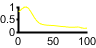

 % plotting spatial distribution - for 242_2 control
 figure
  plot(tmem4.smRIC(:,2004)./max(tmem4.smRIC(:,2004)),'y')
  ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

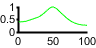

 
figure
  plot(tmem4.smRIC(:,2175)./max(tmem4.smRIC(:,2175)),'g')
   ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

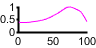

 
 figure
    plot(tmem4.smRIC(:,2707)./max(tmem4.smRIC(:,2707)),'m')
     ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

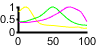

 
  figure  
 tmem4 = load('spatialAnalysis242_2.mat');
 plot(tmem4.smRIC(:,2004)./max(tmem4.smRIC(:,2004)),'y')
 hold on
 % plot(tmem4.smRIC(:,1024)./max(tmem4.smRIC(:,1024)),'g')
 plot(tmem4.smRIC(:,2175)./max(tmem4.smRIC(:,2175)),'g')
  plot(tmem4.smRIC(:,2707)./max(tmem4.smRIC(:,2707)),'m')
 ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

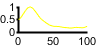

 % for 326_2 cKO
 
  figure
  plot(tectaTM3.smRIC(:,3821)./max(tectaTM3.smRIC(:,3821)),'y')
  ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

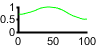

 
figure
  plot(tectaTM3.smRIC(:,2678)./max(tectaTM3.smRIC(:,2678)),'g')
   ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

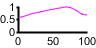

 
 figure
    plot(tectaTM3.smRIC(:,2709)./max(tectaTM3.smRIC(:,2709)),'m')
     ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

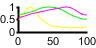

 
  figure  
 plot(tectaTM3.smRIC(:,3821)./max(tectaTM3.smRIC(:,3821)),'y')
 hold on
 plot(tectaTM3.smRIC(:,2678)./max(tectaTM3.smRIC(:,2678)),'g')
  plot(tectaTM3.smRIC(:,2709)./max(tectaTM3.smRIC(:,2709)),'m')
 ylim([0 1])
 figQuality(gcf,gca,[1 0.5])

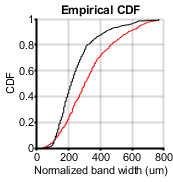

% event bandwidth analysis - currently pixels, need to scale

perctile = 0.75;
scale = 7.6777; % microns perpixel
% calculate BW of all normalized events 
tmem1BW = getSpatialBW(tmem1,perctile);
tmem2BW = getSpatialBW(tmem2,perctile);
tmem3BW = getSpatialBW(tmem3,perctile);
tmem4BW = getSpatialBW(tmem4,perctile);
tmem5BW = getSpatialBW(tmem5,perctile);
tmem6BW = getSpatialBW(tmem6,perctile);

tmemBW = [tmem1BW,tmem2BW, tmem3BW, tmem4BW, tmem5BW, tmem6BW]*scale;

tectaTM1BW = getSpatialBW(tectaTM1,perctile);
tectaTM2BW = getSpatialBW(tectaTM2,perctile);
tectaTM3BW = getSpatialBW(tectaTM3,perctile);
tectaTM4BW = getSpatialBW(tectaTM4,perctile);
tectaTM5BW = getSpatialBW(tectaTM5,perctile);
tectaTM6BW = getSpatialBW(tectaTM6,perctile);
tectaTM7BW = getSpatialBW(tectaTM7,perctile);
tectaTM8BW = getSpatialBW(tectaTM8,perctile);

tectaTMBW = [tectaTM1BW,tectaTM2BW,tectaTM3BW,tectaTM4BW,tectaTM5BW,tectaTM6BW,tectaTM7BW,tectaTM8BW]*scale;

figure
h1 = cdfplot(tectaTMBW);
hold on
h2 = cdfplot(tmemBW);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized band width (um)');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.8 1.9])

[h p] = kstest2(tectaTMBW,tmemBW);
 p

p = 1.6325e-23

 
 % mean bandwidth by animal
 tmemBWmean = [mean(tmem1BW),mean(tmem2BW),mean(tmem3BW),mean(tmem4BW),mean(tmem5BW),mean(tmem6BW)]*scale;
 tectaTMBWmean = [mean(tectaTM1BW),mean(tectaTM2BW),mean(tectaTM3BW),mean(tectaTM4BW),mean(tectaTM5BW),mean(tectaTM6BW),mean(tectaTM7BW),mean(tectaTM8BW)]*scale;
 
 conditions2 = {'Con','cKO'};
dim = [0.6 1.2];
ylbl1 = 'Mean band width (um)';
[fig1 h p1] = compare2(tmemBWmean,tectaTMBWmean,conditions2,ylbl1,dim);

not normal


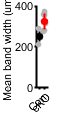

ylim([0 400])
yticks([0 200 400])

p1

p1 = 0.0020

mean(tmemBWmean)

ans = 249.9742

mean(tectaTMBWmean)

ans = 325.6456

std(tmemBWmean)

ans = 25.4212

std(tectaTMBWmean)

ans = 41.3954

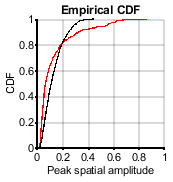


% bandwidth excluding large amplitude events (reviewer figure) 

% plot distribution of dominant amplitudes
tmemDomAmp = [tmem1.eventStats.domAmp,tmem2.eventStats.domAmp,tmem3.eventStats.domAmp,tmem4.eventStats.domAmp,tmem5.eventStats.domAmp,tmem6.eventStats.domAmp];
tectaTMDomAmp = [tectaTM1.eventStats.domAmp,tectaTM2.eventStats.domAmp,tectaTM3.eventStats.domAmp,tectaTM4.eventStats.domAmp,tectaTM5.eventStats.domAmp,tectaTM6.eventStats.domAmp,tectaTM7.eventStats.domAmp,tectaTM8.eventStats.domAmp];

figure
h1 = cdfplot(tectaTMDomAmp*100);
hold on
h2 = cdfplot(tmemDomAmp*100);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Peak spatial amplitude');
ylabel('CDF');
xlim([0 100])
xticks([0 20 40 60 80 100])
figQuality(gcf,gca,[1.8 1.9])

[h p] = kstest2(tmemDomAmp,tectaTMDomAmp);
 p

p = 8.7458e-22

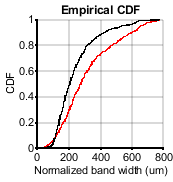


 % OK 0.3 looks like a good cutoff - covers all control events but excludes
 % top 15-20% of cKO event amplitudes
 
 perctile = 0.75;
 thresh = 0.2;
scale = 7.6777; % microns perpixel
% calculate BW of all normalized events 
tmem1BW = getSpatialBWcutoff(tmem1,perctile,thresh);
tmem2BW = getSpatialBWcutoff(tmem2,perctile,thresh);
tmem3BW = getSpatialBWcutoff(tmem3,perctile,thresh);
tmem4BW = getSpatialBWcutoff(tmem4,perctile,thresh);
tmem5BW = getSpatialBWcutoff(tmem5,perctile,thresh);
tmem6BW = getSpatialBWcutoff(tmem6,perctile,thresh);
tmemBW = [];
tmemBW = rmmissing([tmem1BW,tmem2BW, tmem3BW, tmem4BW, tmem5BW, tmem6BW]*scale);

tectaTM1BW = getSpatialBWcutoff(tectaTM1,perctile,thresh);
tectaTM2BW = getSpatialBWcutoff(tectaTM2,perctile,thresh);
tectaTM3BW = getSpatialBWcutoff(tectaTM3,perctile,thresh);
tectaTM4BW = getSpatialBWcutoff(tectaTM4,perctile,thresh);
tectaTM5BW = getSpatialBWcutoff(tectaTM5,perctile,thresh);
tectaTM6BW = getSpatialBWcutoff(tectaTM6,perctile,thresh);
tectaTM7BW = getSpatialBWcutoff(tectaTM7,perctile,thresh);
tectaTM8BW = getSpatialBWcutoff(tectaTM8,perctile,thresh);
tectaTMBW = [];
tectaTMBW = rmmissing([tectaTM1BW,tectaTM2BW,tectaTM3BW,tectaTM4BW,tectaTM5BW,tectaTM6BW,tectaTM7BW,tectaTM8BW]*scale);

figure
h1 = cdfplot(tectaTMBW);
hold on
h2 = cdfplot(tmemBW);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized band width (um)');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.8 1.9])

[h p] = kstest2(tectaTMBW,tmemBW);
 p

p = 2.5509e-12

 
 % mean bandwidth by animal
 tmemBWmean = [nanmean(tmem1BW),nanmean(tmem2BW),nanmean(tmem3BW),nanmean(tmem4BW),nanmean(tmem5BW),nanmean(tmem6BW)]*scale;
 tectaTMBWmean = [nanmean(tectaTM1BW),nanmean(tectaTM2BW),nanmean(tectaTM3BW),nanmean(tectaTM4BW),nanmean(tectaTM5BW),nanmean(tectaTM6BW),nanmean(tectaTM7BW),nanmean(tectaTM8BW)]*scale;
 figure
 conditions2 = {'Control','cKO'};
dim = [1 2];
ylbl1 = 'Mean band width (um)';
[fig1 h p1] = compare2(tmemBWmean,tectaTMBWmean,conditions2,ylbl1,dim);

not normal


ylim([0 400])
yticks([0 100 200 300 400])
p1

p1 = 0.0036

mean(tmemBWmean)

ans = 245.2237

mean(tectaTMBWmean)

ans = 315.4374

std(tmemBWmean)

ans = 25.9944

std(tectaTMBWmean)

ans = 41.6946

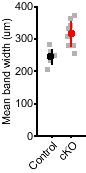

 
 subP = handleTheSubplot({fig1,fig1,fig1},[1 3]);

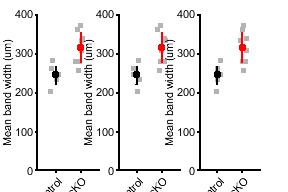

figQuality(subP,gca,[3.2 1.9])

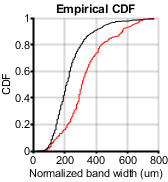

% % event bandwidth, P10

addpath('259_1 tecta wt','242_4 flfl','292_1 tecta wt','287_1 flfl','219_1 tecta flfl','219_2 tecta flfl','225_2 tecta flfl','242_3 tecta flfl')

tmem1 = load('spatialAnalysis259_1.mat');
tmem2 = load('spatialAnalysis292_1.mat');
tmem3 = load('spatialAnalysis242_4.mat');
tmem4 = load('spatialAnalysis287_1.mat');
scale = 7.6777; % microns perpixel
perctile = 0.75;
% calculate BW of all normalized events 
tmem1BW = getSpatialBW(tmem1,perctile);
tmem2BW = getSpatialBW(tmem2,perctile);
tmem3BW = getSpatialBW(tmem3,perctile);
tmem4BW = getSpatialBW(tmem4,perctile);

tmemBW = [tmem1BW,tmem2BW,tmem3BW,tmem4BW]*scale;

tectaTM1 = load('spatialAnalysis219_1.mat');
tectaTM2 = load('spatialAnalysis219_2.mat');
tectaTM3 = load('spatialAnalysis225_2.mat');
tectaTM4 = load('spatialAnalysis242_3.mat');

tectaTM1BW = getSpatialBW(tectaTM1,perctile);
tectaTM2BW = getSpatialBW(tectaTM2,perctile);
tectaTM3BW = getSpatialBW(tectaTM3,perctile);
tectaTM4BW = getSpatialBW(tectaTM4,perctile);

tectaTMBW = [tectaTM1BW,tectaTM2BW,tectaTM3BW,tectaTM4BW]*scale;

figure
h1 = cdfplot(tectaTMBW);
hold on
h2 = cdfplot(tmemBW);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Normalized band width (um)');
ylabel('CDF');
xlim([0 800])
xticks([0 200 400 600 800])
figQuality(gcf,gca,[1.75 1.9])

[h p] = kstest2(tectaTMBW,tmemBW);
 p

p = 3.3537e-27

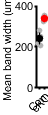

 
 
  % mean bandwidth by animal
 tmemBWmean = [mean(tmem1BW),mean(tmem2BW),mean(tmem3BW),mean(tmem4BW)]*scale;
 tectaTMBWmean = [mean(tectaTM1BW),mean(tectaTM2BW),mean(tectaTM3BW),mean(tectaTM4BW)]*scale;
 
 conditions2 = {'Con','cKO'};
dim = [0.5 1.2];
ylbl1 = 'Mean band width (um)';
[fig1 h p1] = compare2(tmemBWmean,tectaTMBWmean,conditions2,ylbl1,dim);
ylim([0 400])
yticks([0 200 400])

p1

p1 = 0.0018